# Fourier Analysis of Signals Using DFT (250 Points)

**Dear Student, **

**Welcome to Lab 2! At the end of this lab, you will be able to **

- **find out an estimate of frequency content of a discrete-time sequence,  **

- **comment on resolution and leakage of a window and its impact on the frequency analysis, and **

- **compare different types of windows.**

- **use short-term Fourier transform and obtain power spectral density of a signal. **

Let $x[n] =  A_0\cos(w_0n) +  A_1\cos(w_1n), n \in \mathbb{Z}$ be the discrete-time signal obtained by sampling $x(t)$with sampling frequency $T_s$. 

Write down possible expressions for $x(t)$ here:  $\textrm{ENTER}\;\textrm{YOUR}\;\textrm{ANSWER}\;\textrm{HERE}\ldotp$ 


$$x(t) =  A_0\cos(w_0t) +  A_1\cos(w_1t) + Asin(wt), t \in \mathbb{R} ,w =2\pi T_s$$


Usually, we cannot obtain the sequence $x[n]$for all the time duration, i.e., for $-\infty $to $+\infty
$. Further, even if you are able to collect a large number of samples, we will not be able to compute its DFT for frequency analysis.  Let us assume that we have $x[n]$values available for $0\leq n\leq L-1$only using which we are required to do frequency analysis. One way to go forward is, we assume that $x[n]=0$ for $n\notin \{0,L-1\}$.  That is, we have the windowed sequence, $v[n]$, defined as follows:$v[n] = x[n]w[n]$, where $w[n] = 1$for $0\leq n\leq L-1$ and $w[n] =0$, otherwise. This window is called as the rectangular window. 

#### Coding Question (10 points)

Write a code to get $x[n], w[n] $and $v[n]$

clc;
clear;
%w0 = 2*pi/6; w1 = 2*pi/3;
%w0 = 2*pi/14; w1 = 2*pi/15;
%w0 = 2*pi/14; w1 = 2*pi/12;
w0 = 2*pi/14; w1 = 2*pi/25;
A1 = 1;
A2 = 1;
L =  64;   % Window length we take it 64 
n=1:1:L   %sampling window

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



x =  A1*cos(w0*n)+A2*cos(w1*n);             % EXERCISE: Construct x[n] defined above  

w = ones(1,L);       % EXERCISE Define a rectangular window of length L, w[n]

v =  x.*w ;% EXERCISE: Compute the windowed sequence, v[n]



Now, we will compute its DFT using the Matlab in-built function ([fft](https://in.mathworks.com/help/matlab/ref/fft.html)). 

#### Coding Question (10 points)

Compute $N$-point DFT, $V[k]$ of $v[n]$ and plot $V[k]$ from $k\in [0, N-1]$

N = [64]; % EXERCISE: Define a suitable N we take 64 in beginning
  
V = fft(v,N) % EXERCISE: Compute N-point DFT

V =   -4.3229 + 0.0000i  -5.0583 + 4.0679i -10.1773 +16.0734i   5.8725 -18.2069i  -7.5339 + 5.1232i  16.6976 -23.6985i   6.2045 - 9.6945i   4.2440 - 6.6621i   3.4093 - 5.1838i   2.9516 - 4.2662i   2.6664 - 3.6242i   2.4742 - 3.1414i   2.3374 - 2.7602i   2.2362 - 2.4483i   2.1591 - 2.1861i   2.0990 - 1.9607i   2.0511 - 1.7636i   2.0126 - 1.5886i   1.9810 - 1.4312i   1.9550 - 1.2879i   1.9335 - 1.1563i   1.9154 - 1.0342i   1.9003 - 0.9200i   1.8877 - 0.8124i   1.8771 - 0.7102i   1.8683 - 0.6126i   1.8610 - 0.5188i   1.8552 - 0.4279i   1.8505 - 0.3396i   1.8470 - 0.2531i   1.8445 - 0.1680i   1.8431 - 0.0838i   1.8426 + 0.0000i   1.8431 + 0.0838i   1.8445 + 0.1680i   1.8470 + 0.2531i   1.8505 + 0.3396i   1.8552 + 0.4279i   1.8610 + 0.5188i   1.8683 + 0.6126i   1.8771 + 0.7102i   1.8877 + 0.8124i   1.9003 + 0.9200i   1.9154 + 1.0342i   1.9335 + 1.1563i   1.9550 + 1.2879i   1.9810 + 1.4312i   2.0126 + 1.5886i   2.0511 + 1.7636i   2.0990 + 1.9607i


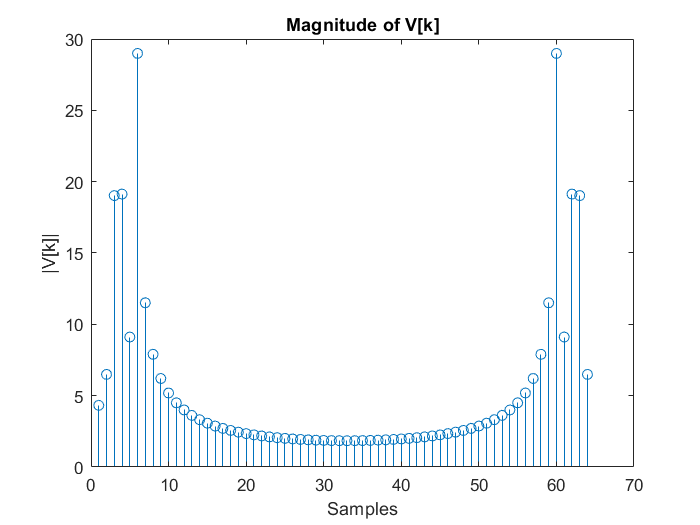

n=1:1:N;

stem(n, abs(V)); %  EXERCISE: Plot Magnitude of V
xlabel('Samples')
ylabel('|V[k]|')
title('Magnitude of V[k]')

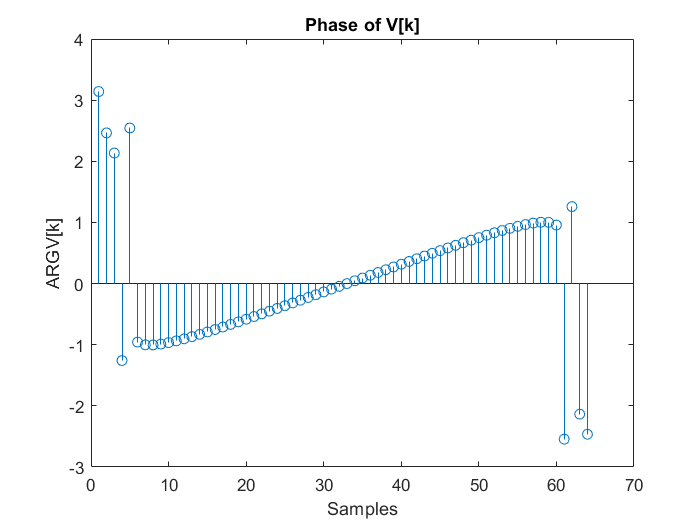


stem(n, angle(V)); %  EXERCISE: Plot Phase of V
xlabel('Samples')
ylabel('ARG{V[k]}')
title('Phase of V[k]')

It is bit difficult to read the above plots as we do not readily see which samples correspond to which discrete-time frequency. Hence, let us try to view the DTFT of v[n] (approximate). Let us first compute the DTFT of $w[n]$.

#### Coding Question (10 points)

Compute the DTFT of w[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

N = N; % EXERCISE: Define a suitable N we use 64 

omega = linspace(-pi,pi,N); % EXERCISE: Compute sample points of discrete-time frequency
%n = 1:length(w)  %To get the term in w which is from 1 to L
%temp=(n)'*omega;  %To make understanding the multiplication with summation easier.
temp=0+0i; %To use to compute the summation
for k=1:length(w)
    temp=temp+w(k)*exp(-j*(k*omega));
end
W= temp  %N-point DFT will be stored in Temp

W =    0.0000 - 0.0000i  -0.0050 - 0.0497i  -0.0198 - 0.0981i  -0.0444 - 0.1440i  -0.0785 - 0.1863i  -0.1218 - 0.2236i  -0.1738 - 0.2549i  -0.2340 - 0.2788i  -0.3018 - 0.2943i  -0.3765 - 0.3003i  -0.4575 - 0.2955i  -0.5438 - 0.2788i  -0.6347 - 0.2491i  -0.7292 - 0.2052i  -0.8264 - 0.1457i  -0.9253 - 0.0693i  -1.0249 + 0.0256i  -1.1243 + 0.1409i  -1.2225 + 0.2790i  -1.3185 + 0.4430i  -1.4113 + 0.6368i  -1.5000 + 0.8660i  -1.5837 + 1.1386i  -1.6617 + 1.4664i  -1.7331 + 1.8678i  -1.7971 + 2.3725i  -1.8533 + 3.0328i  -1.9010 + 3.9474i  -1.9397 + 5.3293i  -1.9691 + 7.7331i  -1.9888 +13.1950i  -1.9988 +40.0489i  -1.9988 -40.0489i  -1.9888 -13.1950i  -1.9691 - 7.7331i  -1.9397 - 5.3293i  -1.9010 - 3.9474i  -1.8533 - 3.0328i  -1.7971 - 2.3725i  -1.7331 - 1.8678i  -1.6617 - 1.4664i  -1.5837 - 1.1386i  -1.5000 - 0.8660i  -1.4113 - 0.6368i  -1.3185 - 0.4430i  -1.2225 - 0.2790i  -1.1243 - 0.1409i  -1.0249 - 0.0256i  -0.9253 + 0.0693i  -0.8264 + 0.1457i


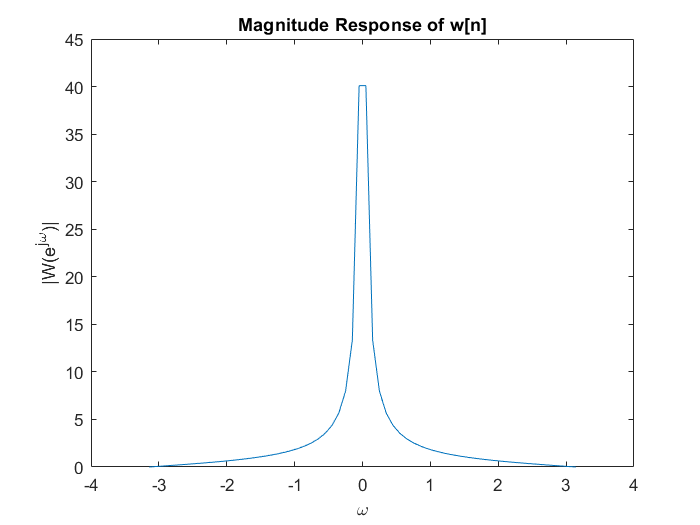

%W = sum(w.*(exp(-j*temp))) % EXERCISE: Compute N-point DFT



plot(omega, abs(W)); %  EXERCISE: Plot Magnitude  of W
xlabel('\omega')
ylabel('|W(e^{j\omega})|')
title('Magnitude Response of w[n]')

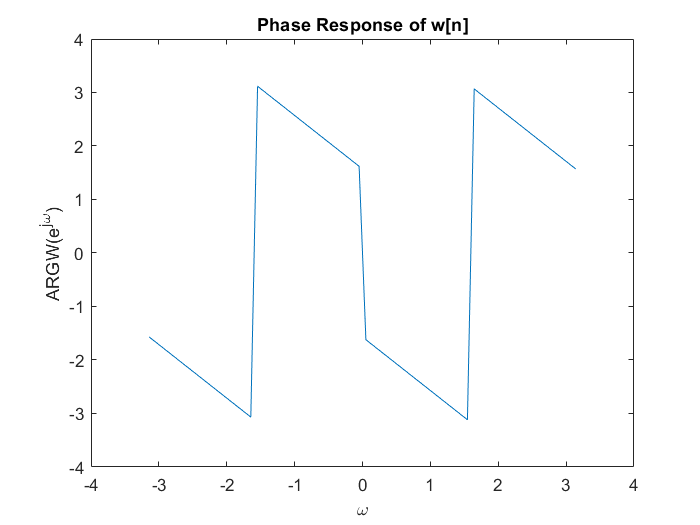


 
plot(omega, angle(W)); %  EXERCISE: Plot Magnitude  of W
xlabel('\omega')
ylabel('ARG{W(e^{j\omega})}')
title('Phase Response of w[n]')

#### Coding Question 10 points)

Compute the DTFT of v[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

N = N; % EXERCISE: Define a suitable N

omega =linspace(-pi,pi,N) % EXERCISE: Compute sample points of discrete-time frequency

omega =    -3.1416   -3.0419   -2.9421   -2.8424   -2.7427   -2.6429   -2.5432   -2.4435   -2.3437   -2.2440   -2.1443   -2.0445   -1.9448   -1.8451   -1.7453   -1.6456   -1.5459   -1.4461   -1.3464   -1.2467   -1.1469   -1.0472   -0.9475   -0.8477   -0.7480   -0.6483   -0.5485   -0.4488   -0.3491   -0.2493   -0.1496   -0.0499    0.0499    0.1496    0.2493    0.3491    0.4488    0.5485    0.6483    0.7480    0.8477    0.9475    1.0472    1.1469    1.2467    1.3464    1.4461    1.5459    1.6456    1.7453


%n = 1:length(v)  %To get the term in w which is from 1 to L
temp=0+0i; %To use to compute the summation
for k=1:length(v)
    temp=temp+v(k)*exp(-j*(k*omega));
end
V= temp  %N point DFT will be saved in temp

V =   -1.8426 + 0.0000i  -1.8335 + 0.1825i  -1.8064 + 0.3632i  -1.7615 + 0.5402i  -1.6992 + 0.7119i  -1.6202 + 0.8766i  -1.5253 + 1.0325i  -1.4154 + 1.1782i  -1.2916 + 1.3123i  -1.1552 + 1.4333i  -1.0075 + 1.5401i  -0.8501 + 1.6316i  -0.6845 + 1.7069i  -0.5124 + 1.7654i  -0.3355 + 1.8063i  -0.1557 + 1.8294i   0.0252 + 1.8344i   0.2052 + 1.8212i   0.3825 + 1.7900i   0.5552 + 1.7412i   0.7211 + 1.6752i   0.8782 + 1.5928i   1.0242 + 1.4948i   1.1567 + 1.3823i   1.2719 + 1.2566i   1.3645 + 1.1193i   1.4230 + 0.9724i  32.9150 + 0.8196i   1.1770 + 0.6728i  33.3099 - 1.5171i   2.5761 + 0.2438i   2.3410 + 0.0847i   2.3410 - 0.0847i   2.5761 - 0.2438i  33.3099 + 1.5171i   1.1770 - 0.6728i  32.9150 - 0.8196i   1.4230 - 0.9724i   1.3645 - 1.1193i   1.2719 - 1.2566i   1.1567 - 1.3823i   1.0242 - 1.4948i   0.8782 - 1.5928i   0.7211 - 1.6752i   0.5552 - 1.7412i   0.3825 - 1.7900i   0.2052 - 1.8212i   0.0252 - 1.8344i  -0.1557 - 1.8294i  -0.3355 - 1.8063i


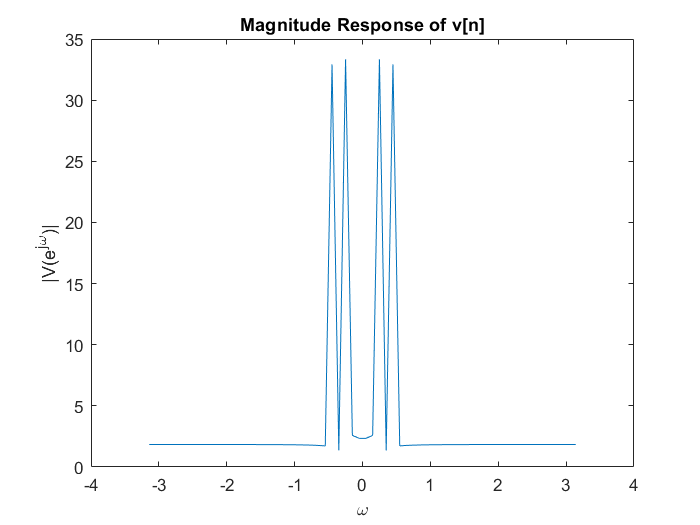

%V = sum(v.*(exp(-j*temp))) % EXERCISE: Compute N-point DFT


plot(omega, abs(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|V(e^{j\omega})|')
title('Magnitude Response of v[n]')

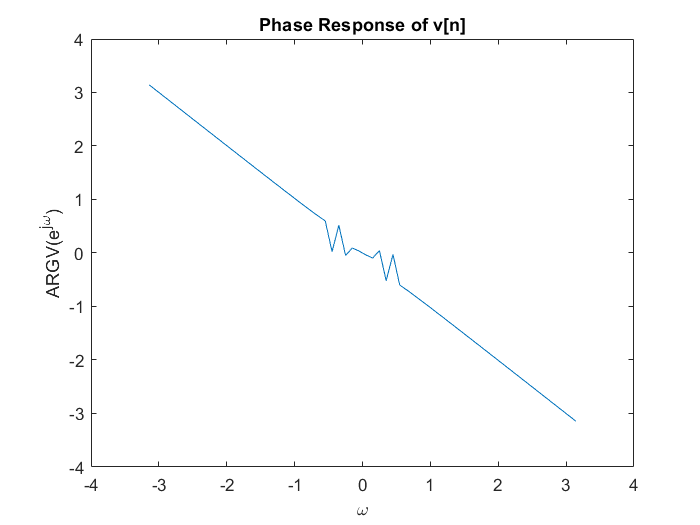


 
plot(omega, angle(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('ARG{V(e^{j\omega})}')
title('Phase Response of v[n]')

#### Coding Question  (10 points)

Now, suppose the $x(t)$ was sampled at sampling period of $T_s$, then plot $X(j\Omega)$, your estimate of the continuous-time Fourier transform of $x(t)$. 

Ts = [0.01] ; % EXERCISE: Choose a sensible sampling frequency

Omega = [-pi:Ts:pi] % EXERCISE: Construct continuous-time frequency from discrete-time frquency

Omega =    -3.1416   -3.1316   -3.1216   -3.1116   -3.1016   -3.0916   -3.0816   -3.0716   -3.0616   -3.0516   -3.0416   -3.0316   -3.0216   -3.0116   -3.0016   -2.9916   -2.9816   -2.9716   -2.9616   -2.9516   -2.9416   -2.9316   -2.9216   -2.9116   -2.9016   -2.8916   -2.8816   -2.8716   -2.8616   -2.8516   -2.8416   -2.8316   -2.8216   -2.8116   -2.8016   -2.7916   -2.7816   -2.7716   -2.7616   -2.7516   -2.7416   -2.7316   -2.7216   -2.7116   -2.7016   -2.6916   -2.6816   -2.6716   -2.6616   -2.6516


n=1:1:length(x);
temp=0+0i; %To use to compute the summation
for k=1:length(x)
    temp=temp+x(k)*exp(-j*(k*Omega));
end
X_jOmega= temp

X_jOmega =   -1.8426 + 0.0000i  -1.6730 + 0.5122i  -1.2325 + 0.8203i  -0.6984 + 0.8024i  -0.2856 + 0.4677i  -0.1603 - 0.0469i  -0.3730 - 0.5325i  -0.8382 - 0.7913i  -1.3687 - 0.7171i  -1.7510 - 0.3374i  -1.8312 + 0.1970i  -1.5767 + 0.6732i  -1.0898 + 0.9016i  -0.5665 + 0.7921i  -0.2174 + 0.3907i  -0.1831 - 0.1391i  -0.4778 - 0.5821i  -0.9830 - 0.7576i  -1.4955 - 0.5927i  -1.8090 - 0.1514i  -1.7970 + 0.3911i  -1.4640 + 0.8184i  -0.9437 + 0.9605i  -0.4455 + 0.7620i  -0.1700 + 0.3044i  -0.2285 - 0.2262i  -0.5978 - 0.6140i  -1.1297 - 0.7005i  -1.6101 - 0.4484i  -1.8455 + 0.0435i  -1.7406 + 0.5795i  -1.3373 + 0.9459i  -0.7973 + 0.9970i  -0.3381 + 0.7138i  -0.1447 + 0.2119i  -0.2956 - 0.3047i  -0.7306 - 0.6258i  -1.2750 - 0.6195i  -1.7097 - 0.2855i  -1.8593 + 0.2445i  -1.6630 + 0.7595i  -1.1990 + 1.0542i  -0.6538 + 1.0114i  -0.2469 + 0.6499i  -0.1425 + 0.1167i  -0.3835 - 0.3714i  -0.8735 - 0.6155i  -1.4158 - 0.5144i  -1.7919 - 0.1056i  -1.8498 + 0.4490i


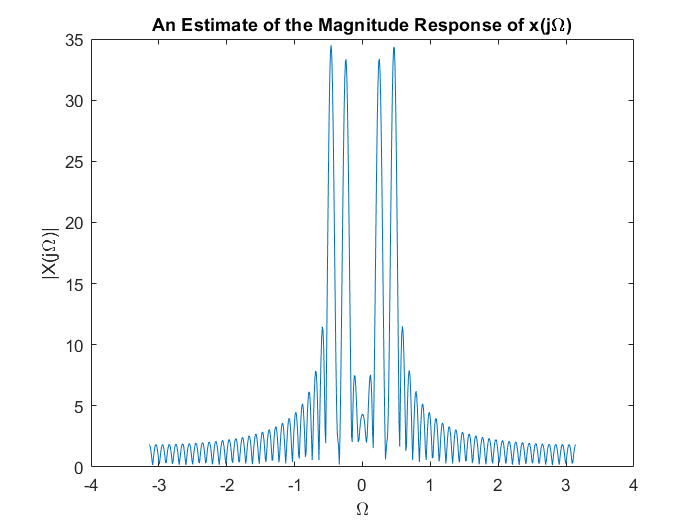

%X_jOmega = sum(x.*exp(-j*(n'.*Omega))) %EXERCISE:  Compute the continuous-time Fourier transform


plot(Omega, abs(X_jOmega)); %  EXERCISE: Plot Magnitude  of V
xlabel('\Omega')
ylabel('|X(j\Omega)|')
title('An Estimate of the Magnitude Response of x(j\Omega)')%

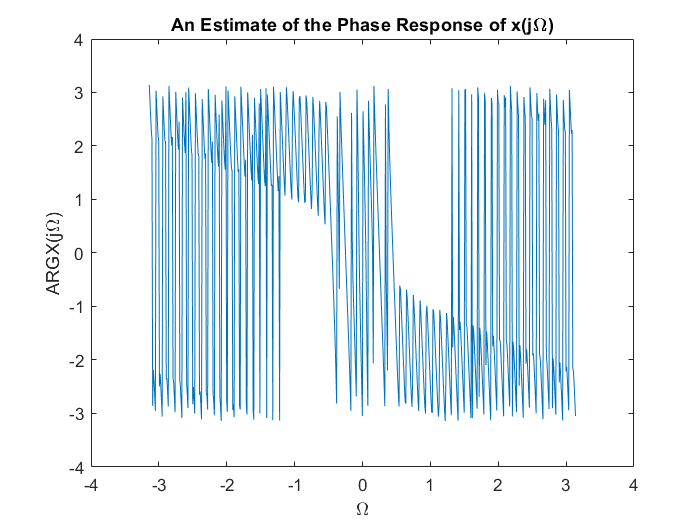



plot(Omega,angle(X_jOmega)); %  EXERCISE: Plot Magnitude  of V
xlabel('\Omega')
ylabel('ARG{X(j\Omega)}')
title('An Estimate of the Phase Response of x(j\Omega)') 

#### Inference Question (40 points)

Now, repeat the above four questions for 

- 
$$w_0 = 2\pi/14, w_1 = 2\pi/15$$


- 
$$w_0 = 2\pi/14, w_1 = 2\pi/12$$


- 
$$w_0 = 2\pi/14, w_1 = 4\pi/25$$


- What do you observe on the number of peaks?  

- How does your observation change if you change $L$? 

- How does your observation change if you change $N$? 

- Do the amplitudes of $|V[k]|$reflect that of $|V(e^{j\omega})|$? Why? 

- Do the amplitudes of $|V(e^{j\omega})|$ reflect that of $|X(e^{j\omega})|$?  Why? 

    * WRITE YOUR ANSWER HERE.*

*1a) |V[k]| peaks got different magnitude while earlier they had same magnitude . But counting highest peak earlier were 4 but later were 2 . *

*b)Increasing L does not change peaks but if we decrease L from N(which is 64) then the peaks start to get joined and get broader . They don't remain that steep and have gradual increase.*

*c)If we decrease N from 64 we see less number of points in plot so it gets difficult to  get points nearby so identifying peak gets more prone to error. while Decreasing N makes graph more dense.*

*d) Yes, both have two main lobe peaks and other side lobe peaks .*

*e) Yes, again both have two main lobe peak and other side lobe peaks*

*2a) Here |V[k]| got 4 high peaks and 2 medium peaks with few other side lobe peaks so we can estimate the 2 main lobe peaks got splitted into 4 main lobe peaks.*

*b) Decreasing L from N(64) makes peaks to join and we see only 2 main lobe peaks while increasing L from 64(N) makes peaks to split more.*

*c)Decreasing N from 64 leads low density of points in plot and we can observe only 1 peak from them while increasing N increases point density of plot and we can see the splitting of Main lobe more clearly .*

*d)*amplitudes of $|V[k]|$do not really reflect that of $|V(e^{j\omega})|$ as $|V[k]|$ has splitted Main lobe while $|V(e^{j\omega})|$ has single main lobe.

e) amplitudes of $|V(e^{j\omega})|$also don't really  reflect that of $|X(e^{j\omega})|$ as $|V(e^{j\omega})|$has single Main lobe while  $|X(e^{j\omega})|$ has splitted main lobe . So $|X(e^{j\omega})|$ actually reflects $|V[k]|$.

3a) *Here |V[k]| has 2 main lobe and 2 side lobe peaks while 4 main lobe peaks in *$|V(e^{j\omega})|$ and $|X(e^{j\omega})|$

b) Decreasing L from 64 causes us to get 2 main lobe peaks which start to join to make single main lobe peak as we decrease L further. While increasing L causes more  splitting  and we see 4 main lobe peaks .

c)Decreasing N from 64 makes  *|V[k]| graph  gets less denser but still  we are able to get 2 main lobe poles though with less accuracy about its magnitude. While increasing N from 64 causes us to clearly identify 4 main lobe poles .*

d) amplitudes of $|V[k]|$don't really reflect that of $|V(e^{j\omega})|$ as has 2 main lobe peaks while $|V(e^{j\omega})|$ has 4 main lobe peaks. That may have caused by taking a lower vaue of N lead to not seeing 2 main lobe poles.

e) amplitudes of $|V(e^{j\omega})|$ reflect that of $|X(e^{j\omega})|$ as both have 4 main lobe peaks. 

In the above, we observed $x[n]$ through a rectangular window. Let's now observe $x[n]$ through other types of windows and explore what we will see. 

Now, use this link for help ([https://in.mathworks.com/help/dsp/ref/windowfunction.html](https://in.mathworks.com/help/dsp/ref/windowfunction.html)) and compute the DTFT of $v[n]$ over $[-\pi, \pi]$when

- $w[n]$is a Hamming window

- $w[n]$is a Hanning window

- $w[n]$is a Bartlet window

- $w[n]$is a Kaiser window

Note that you have already used the Boxcar window earlier above. 

#### Coding Question  (40 points)

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A HAMMING WINDOW

N = 100; % We take N=100 so see data more clearly
w=hamming(length(x));
v=w.*x;
omega =linspace(-pi,pi,N) % EXERCISE: Compute sample points of discrete-time frequency

omega =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


%n = 1:length(v)  %To get the term in w which is from 1 to L
temp=0+0i; %To use to compute the summation
for k=1:length(v)
    temp=temp+v(k)*exp(-j*(k*omega));
end
V= temp  %N point DFT will be saved in temp

V =   -0.0000 - 0.0000i  -0.1182 + 0.0633i  -0.0992 - 0.0660i  -0.0027 + 0.0285i  -0.1341 + 0.0562i  -0.0782 - 0.0635i  -0.0108 + 0.0559i  -0.1459 + 0.0454i  -0.0562 - 0.0553i  -0.0239 + 0.0813i  -0.1528 + 0.0320i  -0.0344 - 0.0410i  -0.0415 + 0.1036i  -0.1542 + 0.0172i  -0.0142 - 0.0206i  -0.0629 + 0.1220i  -0.1495 + 0.0024i   0.0034 + 0.0061i  -0.0873 + 0.1358i  -0.1384 - 0.0110i   0.0170 + 0.0389i  -0.1136 + 0.1445i  -0.1206 - 0.0213i   0.0256 + 0.0778i  -0.1407 + 0.1475i  -0.0958 - 0.0265i   0.0277 + 0.1226i  -0.1672 + 0.1449i  -0.0639 - 0.0244i   0.0221 + 0.1735i  -0.1915 + 0.1363i  -0.0244 - 0.0121i   0.0073 + 0.2309i  -0.2114 + 0.1221i   0.0235 + 0.0146i  -0.0188 + 0.2956i  -0.2235 + 0.1021i   0.0813 + 0.0619i  -0.0589 + 0.3678i  -0.2202 + 0.0762i   0.1507 + 0.1391i  -0.1138 + 0.4385i  -0.1769 + 0.0429i   0.2170 + 0.2426i  -0.1403 + 0.3855i   0.0508 - 0.0073i  -0.1713 - 0.2327i   2.1622 - 4.5424i -29.2069 + 1.3913i  30.1752 +50.4010i


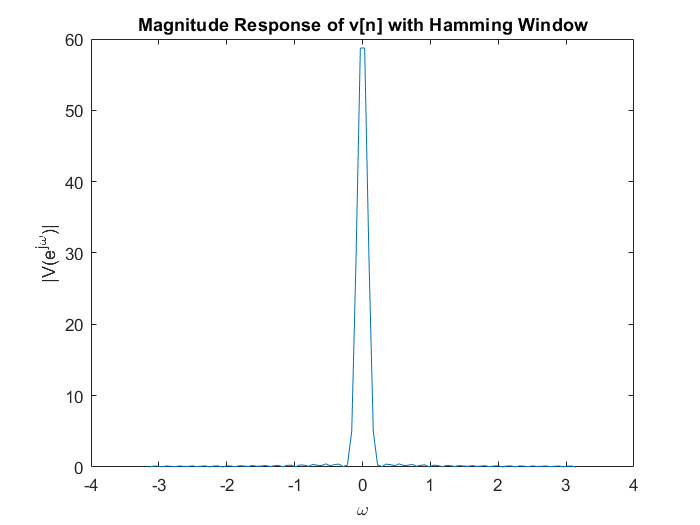

%V = sum(v.*(exp(-j*temp))) % EXERCISE: Compute N-point DFT


plot(omega, abs(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|V(e^{j\omega})|')
title('Magnitude Response of v[n] with Hamming Window')

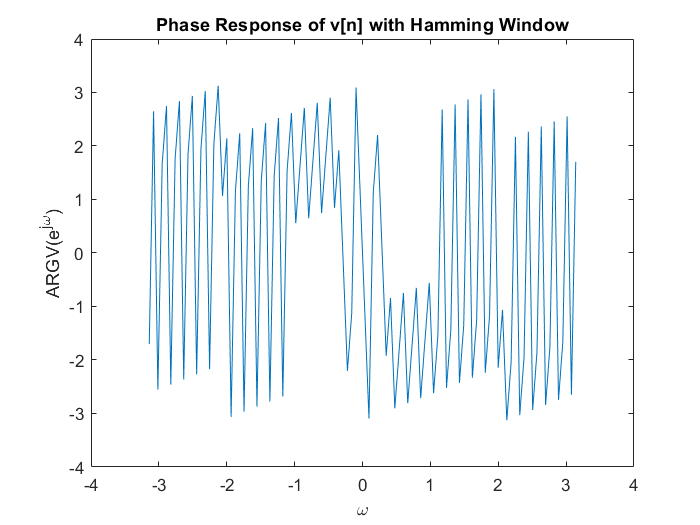


 
plot(omega, angle(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('ARG{V(e^{j\omega})}')
title('Phase Response of v[n] with Hamming Window')

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Hanning WINDOW

N = N;  %We use N=64 everytime
w=hann(length(x));
v=w.*x;
omega =linspace(-pi,pi,N) % EXERCISE: Compute sample points of discrete-time frequency

omega =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


%n = 1:length(v)  %To get the term in w which is from 1 to L
temp=0+0i; %To use to compute the summation
for k=1:length(v)
    temp=temp+v(k)*exp(-j*(k*omega));
end
V= temp  %N point DFT will be saved in temp

V =   -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0001 + 0.0001i  -0.0000 + 0.0002i  -0.0000 + 0.0000i   0.0002 + 0.0002i  -0.0001 + 0.0004i   0.0001 - 0.0000i   0.0004 + 0.0004i  -0.0001 + 0.0005i   0.0003 - 0.0001i   0.0006 + 0.0007i  -0.0002 + 0.0004i   0.0008 - 0.0001i   0.0007 + 0.0011i  -0.0001 + 0.0002i   0.0014 - 0.0000i   0.0008 + 0.0014i   0.0002 - 0.0003i   0.0023 + 0.0002i   0.0007 + 0.0016i   0.0008 - 0.0010i   0.0033 + 0.0006i   0.0005 + 0.0015i   0.0019 - 0.0020i   0.0045 + 0.0012i   0.0002 + 0.0008i   0.0040 - 0.0035i   0.0057 + 0.0022i  -0.0002 - 0.0012i   0.0076 - 0.0054i   0.0067 + 0.0033i  -0.0002 - 0.0056i   0.0141 - 0.0081i   0.0069 + 0.0043i   0.0010 - 0.0157i   0.0261 - 0.0119i   0.0043 + 0.0033i   0.0065 - 0.0404i   0.0511 - 0.0177i  -0.0091 - 0.0084i   0.0295 - 0.1139i   0.1147 - 0.0278i  -0.0779 - 0.0871i   0.1628 - 0.4473i   0.3738 - 0.0537i  -0.8251 - 1.1206i   3.1738 - 6.6677i -31.4222 + 1.4968i  28.3267 +47.3135i


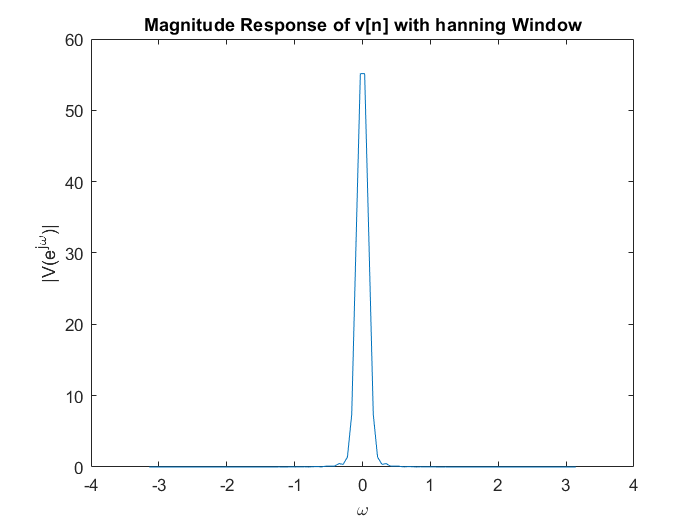

%V = sum(v.*(exp(-j*temp))) % EXERCISE: Compute N-point DFT


plot(omega, abs(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|V(e^{j\omega})|')
title('Magnitude Response of v[n] with hanning Window')

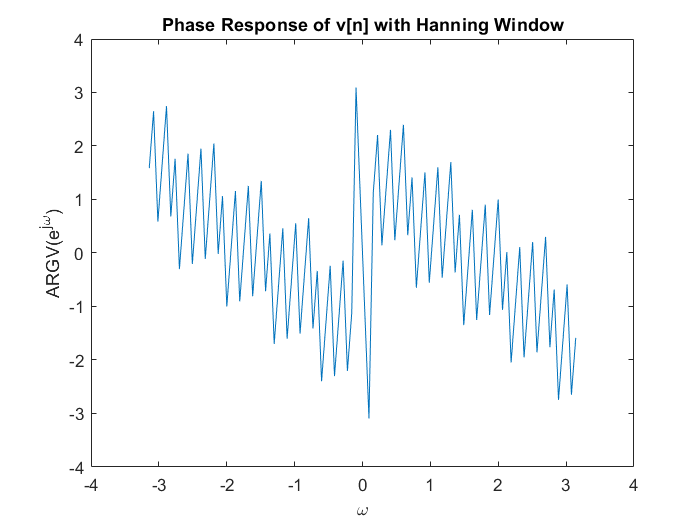


 
plot(omega, angle(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('ARG{V(e^{j\omega})}')
title('Phase Response of v[n] with Hanning Window')

%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Bartlet WINDOW
N = N; %We use N=64 everytime
w=bartlett(length(x));
v=w.*x;
omega =linspace(-pi,pi,N) % EXERCISE: Compute sample points of discrete-time frequency

omega =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


%n = 1:length(v)  %To get the term in w which is from 1 to L
temp=0+0i; %To use to compute the summation
for k=1:length(v)
    temp=temp+v(k)*exp(-j*(k*omega));
end
V= temp  %N point DFT will be saved in temp

V =    0.0000 + 0.0000i   0.0246 - 0.0132i   0.0172 + 0.0114i   0.0005 - 0.0056i   0.0311 - 0.0130i   0.0090 + 0.0073i   0.0020 - 0.0106i   0.0360 - 0.0112i   0.0007 + 0.0007i   0.0043 - 0.0147i   0.0393 - 0.0082i  -0.0074 - 0.0088i   0.0069 - 0.0172i   0.0406 - 0.0045i  -0.0147 - 0.0213i   0.0091 - 0.0177i   0.0399 - 0.0006i  -0.0207 - 0.0371i   0.0102 - 0.0158i   0.0370 + 0.0029i  -0.0247 - 0.0565i   0.0087 - 0.0110i   0.0320 + 0.0056i  -0.0263 - 0.0800i   0.0026 - 0.0027i   0.0251 + 0.0069i  -0.0245 - 0.1084i  -0.0112 + 0.0097i   0.0164 + 0.0063i  -0.0183 - 0.1433i  -0.0383 + 0.0273i   0.0067 + 0.0033i  -0.0060 - 0.1877i  -0.0890 + 0.0514i  -0.0032 - 0.0020i   0.0158 - 0.2481i  -0.1864 + 0.0851i  -0.0107 - 0.0081i   0.0543 - 0.3393i  -0.3895 + 0.1348i  -0.0086 - 0.0080i   0.1307 - 0.5039i  -0.8963 + 0.2175i   0.0326 + 0.0365i   0.3315 - 0.9107i  -2.7547 + 0.3961i   0.3410 + 0.4631i   1.4522 - 3.0509i -26.0368 + 1.2403i  27.8092 +46.4490i


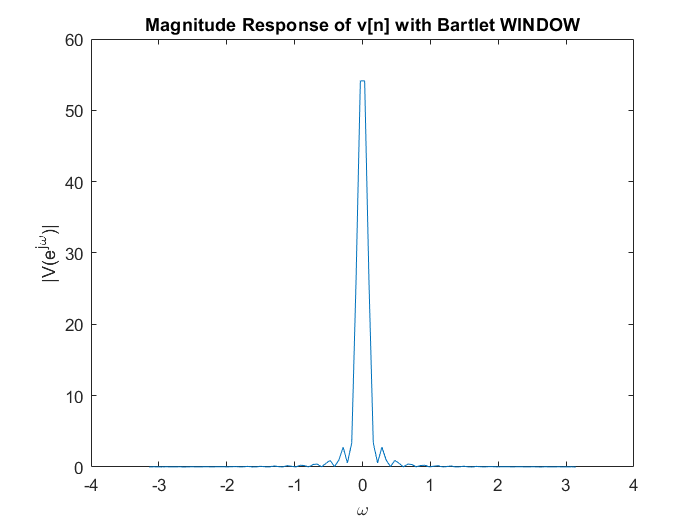

%V = sum(v.*(exp(-j*temp))) % EXERCISE: Compute N-point DFT


plot(omega, abs(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|V(e^{j\omega})|')
title('Magnitude Response of v[n] with Bartlet WINDOW')

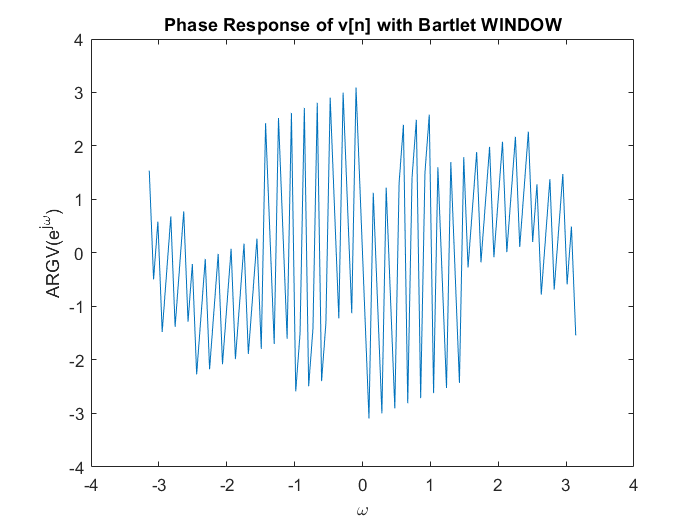


 
plot(omega, angle(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('ARG{V(e^{j\omega})}')
title('Phase Response of v[n] with Bartlet WINDOW')


%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Kaiser WINDOW
N = N; % %We use N=64 everytime
w=kaiser(length(x));
v=w.*x;
omega =linspace(-pi,pi,N) % EXERCISE: Compute sample points of discrete-time frequency

omega =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


%n = 1:length(v)  %To get the term in w which is from 1 to L
temp=0+0i; %To use to compute the summation
for k=1:length(v)
    temp=temp+v(k)*exp(-j*(k*omega));
end
V= temp  %N point DFT will be saved in temp

V =    0.0000 - 0.0000i  -1.3863 + 0.7428i  -1.1648 - 0.7750i  -0.0317 + 0.3317i  -1.5723 + 0.6586i  -0.9198 - 0.7473i  -0.1256 + 0.6514i  -1.7121 + 0.5324i  -0.6641 - 0.6537i  -0.2783 + 0.9477i  -1.7965 + 0.3759i  -0.4113 - 0.4902i  -0.4843 + 1.2097i  -1.8180 + 0.2028i  -0.1751 - 0.2544i  -0.7362 + 1.4281i  -1.7706 + 0.0281i   0.0303 + 0.0545i  -1.0250 + 1.5950i  -1.6499 - 0.1312i   0.1912 + 0.4368i  -1.3403 + 1.7044i  -1.4528 - 0.2562i   0.2933 + 0.8930i  -1.6709 + 1.7524i  -1.1764 - 0.3252i   0.3220 + 1.4258i  -2.0049 + 1.7373i  -0.8172 - 0.3122i   0.2607 + 2.0428i  -2.3307 + 1.6597i  -0.3678 - 0.1823i   0.0877 + 2.7634i  -2.6372 + 1.5226i   0.1884 + 0.1169i  -0.2308 + 3.6310i  -2.9149 + 1.3312i   0.8909 + 0.6780i  -0.7596 + 4.7471i  -3.1576 + 1.0928i   1.8407 + 1.7002i  -1.6538 + 6.3739i  -3.3691 + 0.8173i   3.3445 + 3.7382i  -3.4132 + 9.3778i  -3.6075 + 0.5187i   6.7950 + 9.2288i  -9.0170 +18.9431i  -5.1330 + 0.2445i  50.5319 +84.4022i


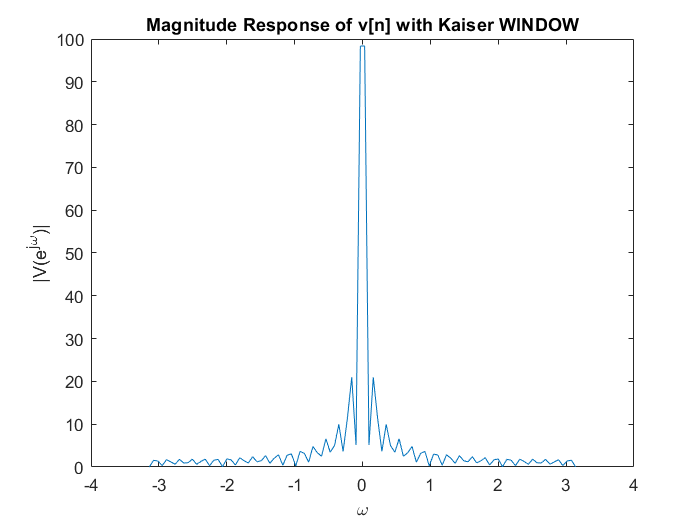

%V = sum(v.*(exp(-j*temp))) % EXERCISE: Compute N-point DFT


plot(omega, abs(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|V(e^{j\omega})|')
title('Magnitude Response of v[n] with Kaiser WINDOW')

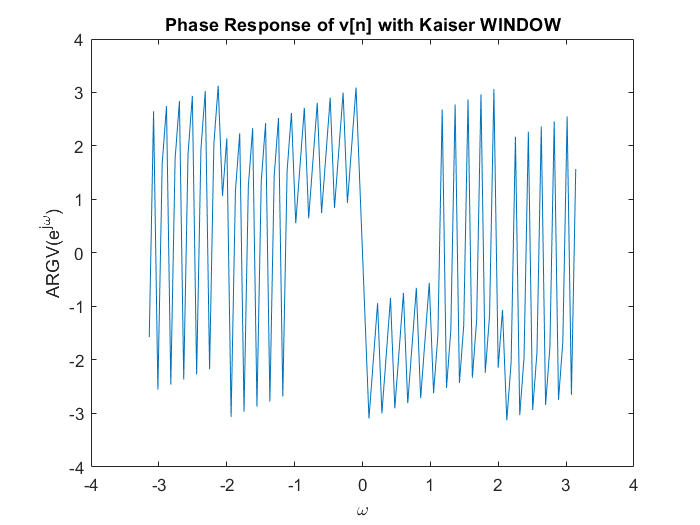


 
plot(omega, angle(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('ARG{V(e^{j\omega})}')
title('Phase Response of v[n] with Kaiser WINDOW')

#### Inference Question  (20 points)

- What do you observe on the number of peaks and their amplitudes?

- Give a short comparison of different windows on  the above terms (on the number of peaks and their amplitudes) that you can observe. 

    * WRITE YOUR ANSWER HERE.*

I observe a Main lobe with highest peak with some smaller side lobe peaks in all windows (except Hanning and Hamming where sidelobe peaks are very small as compared to main lobe peak ) and Kaiser window where main lobe peak appeared much higher than othes(with $\left.\beta =10\;\textrm{default}\right)\;\textrm{but}\;\textrm{also}\;\textrm{side}\;\textrm{lobe}\;\textrm{peaks}\;\textrm{were}\;\textrm{significantly}\;\textrm{higher}\ldotp$.

Hamming Window :-The main lobe Peak has amplitude of  57.01 with width(0.22*2 rad)

                             Side lobe peak around 0.45 and there were multiple sidelobe peaks.

Hanning Window :-The main lobe Peak has amplitude of 53.52 with width(0.28*2 rad)

                            Side lobe peak around 0.46 and only 1 side lobe was visible

Barlet Window :-The main lobe Peak has amplitude of 52.54 with width(0.22*2 rad)

                            Side Lobe peak was at 2.7 and 3 clear side lobes were visible.

kaiser Window:-(with $\left.\beta =10\;\textrm{default}\right)$The main lobe Peak has amplitude 95.48 with 

                            width(0.095*2) The side Lobe peak was at 20.36 and there were many side 

                            lobes ,so we see lower side lobe amplitude will result in lower main lobe width .

## Short-Time Fourier Transform (50 Points)

In the above material, we assume that the frequencies and amplitudes of the sinusoids do not change with time. However, in practice, usually amplitudes and frequencies of a signal change with time. For analyzing the frequency content of that we consider only a small window and analyse its frequency content, and slide the window to look at the frequency content of the next window and so on. This is called the Short-Time Fourier Transform. 

Now read the first page of Section 10.3 of "Discrete-Time Signal Processing", 2nd Edition by Alan V. Oppenheim, Ronald Schafer and John R. Buck. 

- How is the short-time Fourier transform defined as, for a sequence $x[n]$.

        ANSWER:  we take a window of length m and kepp shifting the part of signal which passes through the window making the signal x[m] of two variables x[n+m] where n is used to change the portion of signal x[m]. We then compute the time dependent fourier transform of x[n] as normal fourier transform just with a additional parameter m and we do it for every n to get X[n,$\left.\lambda \right\rbrack \ldotp$.

- Now, construct the following frequency modulated chirp signal: $x[n] = \cos(\omega_0 n^2), $ where $\omega_0 = 2\pi\times 7.5\times10^{-6}. $

n=0:1:2000;%taking some values for n to generate signal
w0= 2*pi*7.5/10^6

w0 = 4.7124e-05

x = cos(w0*n.^2); % ENTER YOUR CODE HERE

- Now compute the short-term Fourier transform of $x[n], $ with rectangular window, $w[n]$  of some L  length. 

L = [400]; % LENGTH OF THE RECTANGULAR WINDOW as 400

w=ones(1,L);% RECTANGULAR WINDOW
lambda=0:0.1:2*pi

lambda =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


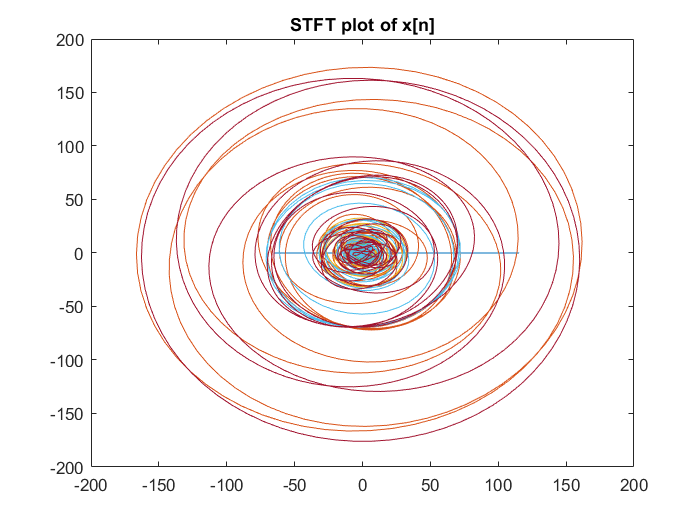

for k=1:length(n)-400 %We repeat the loop for overlapping windows with 399 elements overlapping.
    temp=0+0i;
    for s=1:400
        temp=temp+w(s)*x(k+s)*exp(-j*lambda*s);
    end
    X(k,:)=temp;
end
plot(X);
title("STFT plot of x[n]");

%X[n,w] = []; % COMPUTE STFT of x[n] using rectnagluar window w[n].
             % DISPLAY THE IMAGE IN A TWO DIMENSIONAL PLOT.    
             

- Now use [spectrogram](https://in.mathworks.com/help/signal/ref/spectrogram.html) to compute the short-time Fourier transform of the above $x[n]$ and compare it with what you had got. 

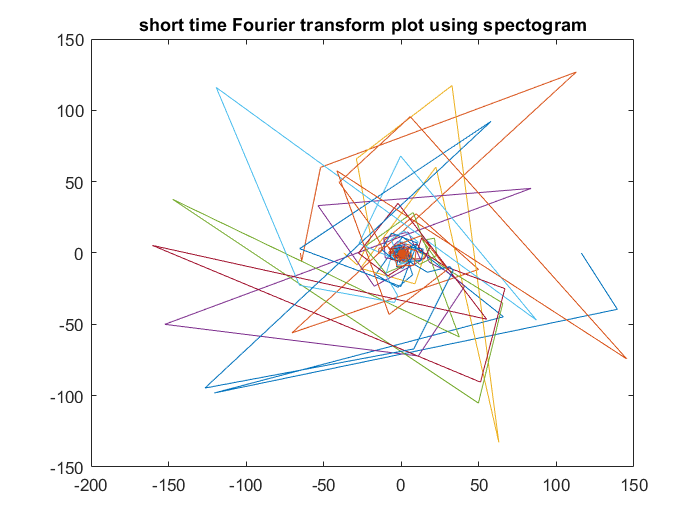

s = spectrogram(x,rectwin(L));  % We used rectangular window here too .
plot(s);
title("short time Fourier transform plot using spectogram");

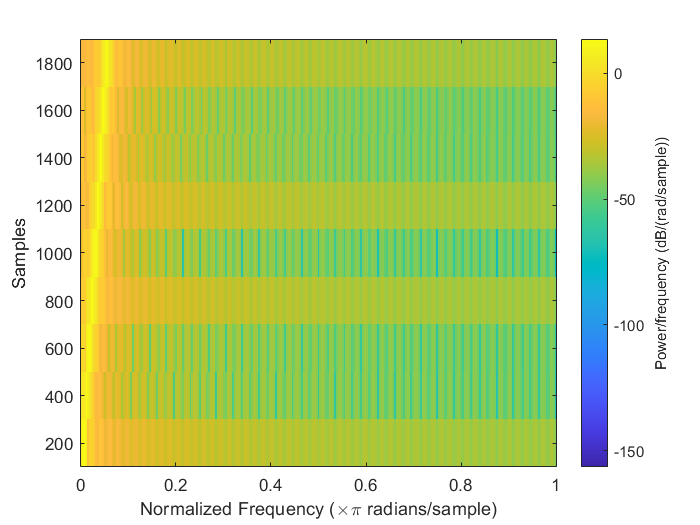

spectrogram(x,rectwin(L))

             %WRITE YOUR CODE HERE

# Practical Experiment (50 Points)

- Now count 1 to 5 in any language of your interest (try your mother tongue) and record it.

rec = audiorecorder(10000,8,1); %to ensure shorter recorded signal.
disp('Start speaking 1,2,3,4,5')

Start speaking 1,2,3,4,5


recordblocking(rec, 5);
disp('End');

End



x = getaudiodata(rec);
             % COUNT 1-5 AND RECORD IT.

- Now compute the spectrogram of the signal you have recorded

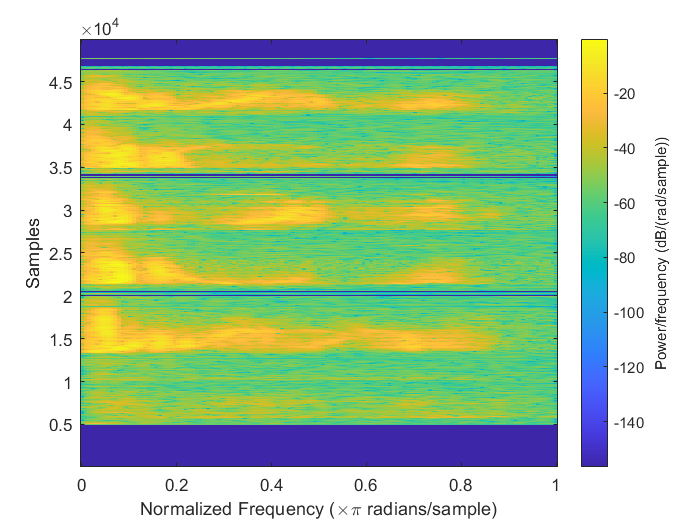

spectrogram(x,100) %we take window of 100

%spectrogram(x,128,100,128,1e3) %On varying some parameters
             % COMPUTE THE SPECTROGRAM

- Play with different parameters of the spectrogram and write your 3 observations: 

        ANSWER:  The yellow part in the spectrogram plot show the frequencies with high power and y axis shows the samples so clearly we can see 5 major partitions from samples which denote the different numbers 1,2,3,4,5. Initially there is some pause as that time I took to start speaking .

- Now compute the [periodogram](https://in.mathworks.com/help/signal/ref/periodogram.html) of the recorded signal:

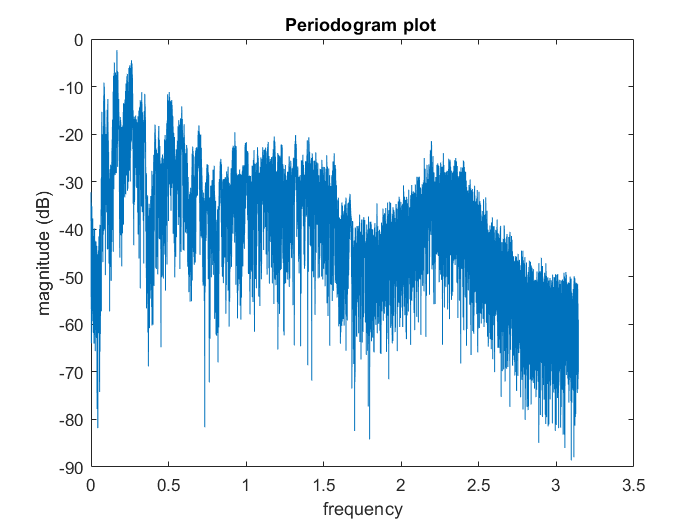

%periodogram(x)
[pxx,w] = periodogram(x);
plot(w,10*log10(pxx))
title("Periodogram plot ");
xlabel("frequency");
ylabel("magnitude (dB)");

pause(1); 
%sound(x); % To see the recorded sound.
             %WRITE YOUR CODE HERE

- What information does the periodogram give? 

        ANSWER:  Periodogram gives an estimate about the power different frequencies in the signal contain ie. Power spectral Density estimate.

- Until what frequency does human voice contain significant power density? 

        ANSWER: Looking at the plot Human voice contains significant power density upto 2.5 KHz

## Thank You!